# 3-D (Linear) Geometric Transformations

The following matrix stores the 8 vertices of a rectangular prism:

$X= \left[\matrix{0 & 0 & 0 & 0 & 1 & 1 & 1 & 1\cr
 0 & 0 & 1 & 1 & 0 & 0 & 1 & 1\cr
    0 & 1 & 0 & 1 & 0 & 1 & 0 & 1}\right]$, 

which in this case is a unit cube. 

% The shape to be transformed  
X = [   0.0  0.0  0.0;    % 1
        0.0  0.0  1.0;    % 2
        0.0  1.0  0.0;    % 3
        0.0  1.0  1.0;    % 4
        1.0  0.0  0.0;    % 5
        1.0  0.0  1.0;    % 6
        1.0  1.0  0.0;    % 7
        1.0  1.0  1.0 ]'  % 8 

X =      0     0     0     0     1     1     1     1
     0     0     1     1     0     0     1     1
     0     1     0     1     0     1     0     1


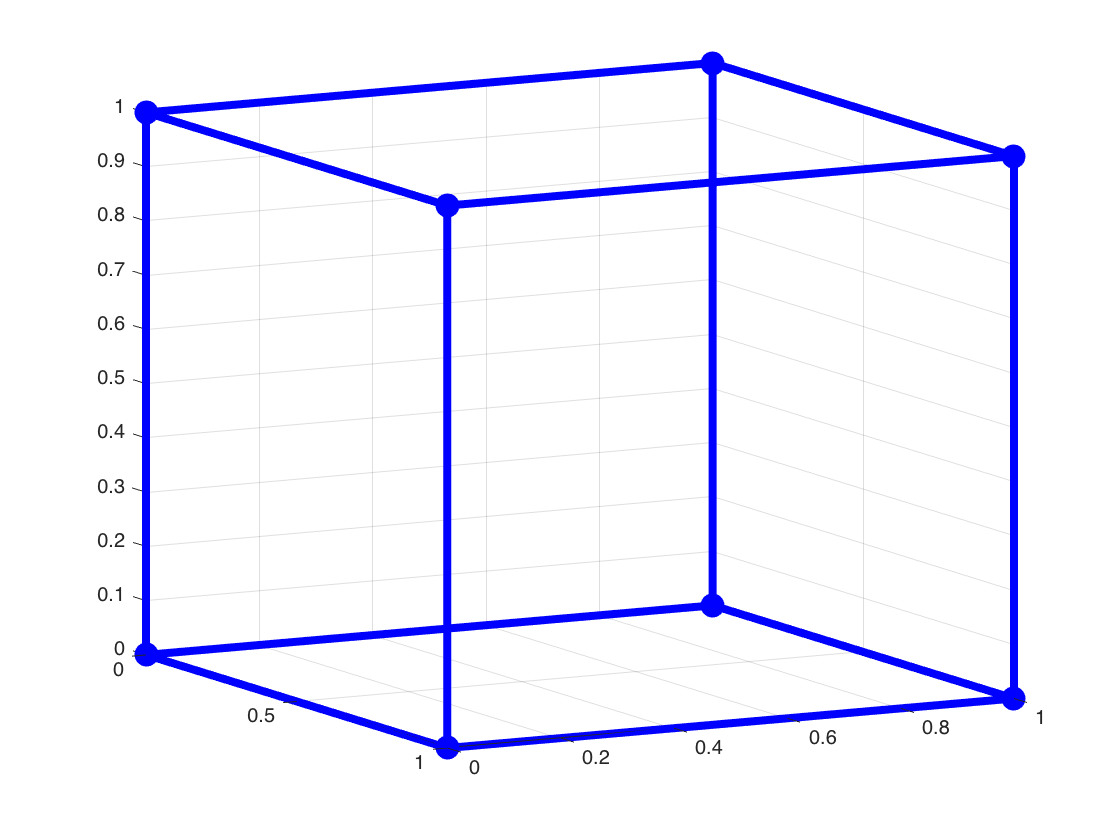

%% 
% First, we display the original shape in blue. The shape will then
% be transformed and the result is displayed in red. All shapes will be
% displayed superimposed on a single plot.
        
% Show original shape in blue
showCube(pts,'blue');  
view(62,11)  

Given a scaling matrix: 


$$S = 
\left[\begin{array}{ccc}
		1/2 & 0 & 0 \\
		0 & 1/2 & 0 \\
		0 &   0 & 1/2
\end{array}\right]$$


We can scale the shape X by half as follows:

$  X^\prime = S\,X = 
\left[\begin{array}{ccc}
		1/2 & 0 & 0 \\
		0 & 1/2 & 0 \\
		0 &   0 & 1/2
\end{array}\right]
\left[\begin{array}{c}
 0 & 0 & 0 & 0 & 1 & 1 & 1 & 1\\ 0 & 0 & 1 & 1 & 0 & 0 & 1 & 1\\ 0 & 1 & 0 & 1 & 0 & 1 & 0 & 1
\end{array}\right]$.

The transformed (scaled) shape is then: 

$  X^\prime = 
\left[\begin{array}{c}
0 & 0 & 0 & 0 & 1/2 & 1/2 & 1/2& 1/2\\ 0 & 0 & 1/2 & 1/2& 0 & 0 & 1/2 & 1/2\\ 0 & 1/2 & 0 & 1/2 & 0 & 1/2& 0 & 1/2
\end{array}\right]$.

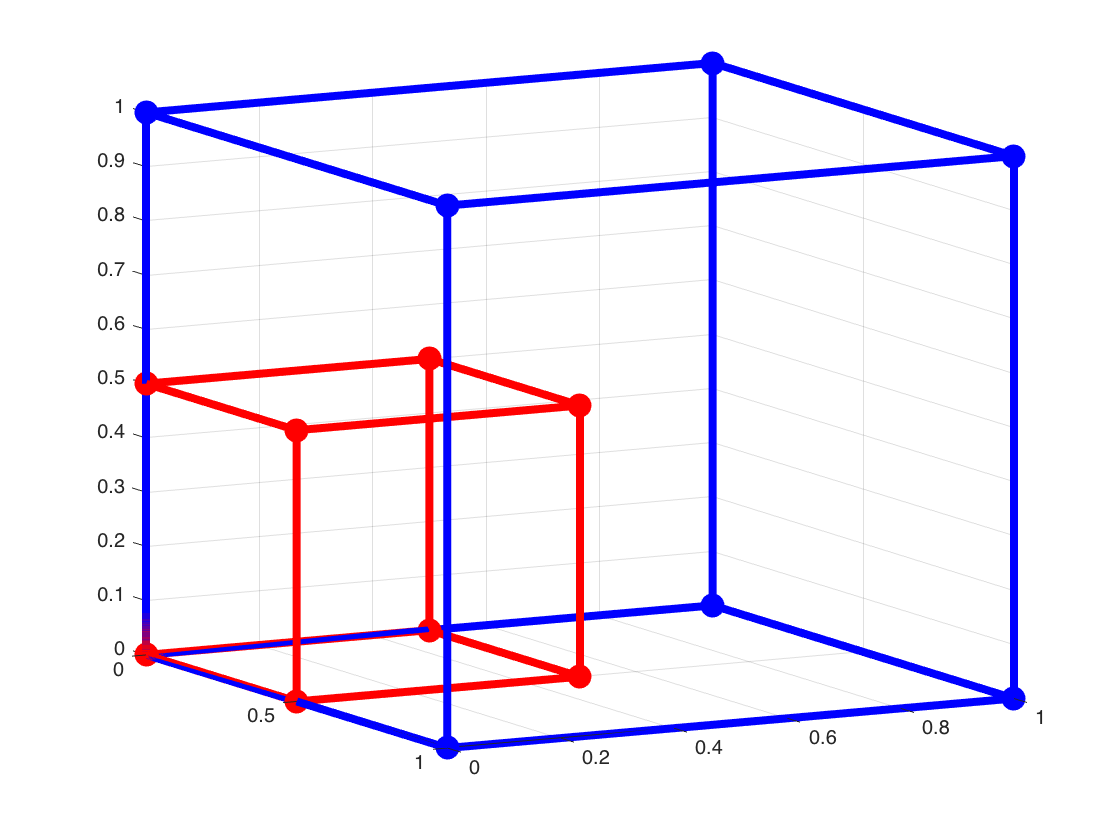

% Transformation matrix (scaling)
S = [ 1/2 0.0 0.0;
      0.0 1/2 0.0;
      0.0 0.0 1/2]; 


% Apply transformation 
X_prime = S * X; 

% Show transformed shape in red
hold on;
showCube(X_prime,'red');   

view(62,11)  

function showCube(x, c )  
%% showCube 
%
% This function plots the cube shape in 3-D. 
%
% Input: 
%   x: (x,y,z) coordinates as 3xM matrix 
%   c: line color 
%
%


hold on;
    
% Indices of bottom square  
idx1 = [ 1 5 7 3 1 ];   
plot3(x(1,idx1),x(2,idx1),x(3,idx1),'Color',c, 'Marker','o','LineWidth',4);
  
% Indices of top square
idx2 = [ 2 6 8 4 2 ];   
plot3(x(1,idx2),x(2,idx2),x(3,idx2),'Color',c, 'Marker','o','LineWidth',4);
 
% Link the two squares
plot3(x(1,1:2),x(2,1:2),x(3,1:2),'Color',c, 'Marker','o','LineWidth',4, 'MarkerSize', 8, 'MarkerFaceColor',c);
plot3(x(1,5:6),x(2,5:6),x(3,5:6),'Color',c, 'Marker','o','LineWidth',4, 'MarkerSize', 8, 'MarkerFaceColor',c);
plot3(x(1,7:8),x(2,7:8),x(3,7:8),'Color',c, 'Marker','o','LineWidth',4, 'MarkerSize', 8, 'MarkerFaceColor',c);
plot3(x(1,3:4),x(2,3:4),x(3,3:4),'Color',c, 'Marker','o','LineWidth',4, 'MarkerSize', 8, 'MarkerFaceColor',c);

grid on;

set(gcf, 'color','w');     

hold off; 

end 